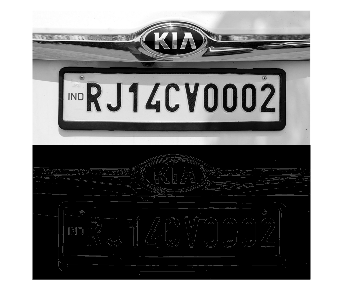

close all;clear; clc;
letter_templates=imageDatastore("Template_letters");

text_plate_letters="";
car_plate="Car_plate_numbers\plate1.jpeg";

plate=blackandwhite(car_plate);
plate=oddandeven(plate);

original_plate=plate;

edges=icanny(plate);
figure, montage({plate, edges}) ; 

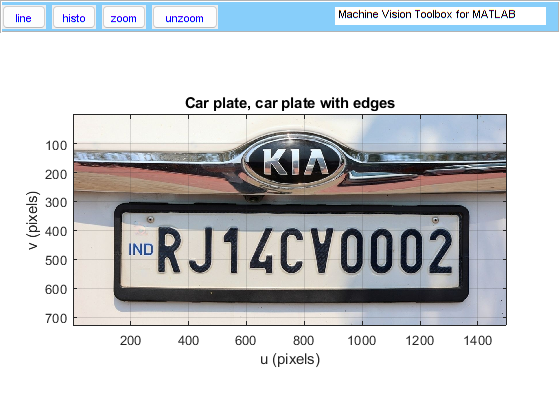

grid on , axis on, title('Car plate, car plate with edges') ;

 
%% Find Hough Horizontal edges
h = Hough(edges)

 
h = 
 
Hough: nd=401, ntheta=400, interp=3x3, distance=1
 


figure, h.show(), grid on ,
lines = h.lines()

 
lines = 
 
theta=-0.00775619, rho=158.253, strength=1        
theta=-0.0315416, rho=124.999, strength=0.972418  
theta=-0.000145041, rho=132.969, strength=0.965928
theta=0.0237234, rho=166.856, strength=0.901568   
theta=0.0146227, rho=184.959, strength=0.891293   
theta=0.109419, rho=325.73, strength=0.884262     
theta=-0.0493251, rho=115.353, strength=0.882098  
theta=0.015147, rho=149.127, strength=0.882098    
theta=0.1259, rho=349.964, strength=0.878853      
theta=0.040654, rho=183.999, strength=0.855598    
theta=-0.0255763, rho=148.756, strength=0.854516  
theta=0.0873751, rho=316, strength=0.845863       
theta=-0.0470454, rho=149.73, strength=0.823148   
theta=-0.00681461, rho=266.258, strength=0.802596 
theta=-0.0150364, rho=591.829, strength=0.799892  
theta=0.00421719, rho=170.641, strength=0.797729  
theta=0.00370063, rho=603.612, strength=0.791239  
theta=0.0854859, rho=296.346, strength=0.784208   
theta=-0.0942451, rho=116.985, strength=0.782044  
theta=-0.0709235, 

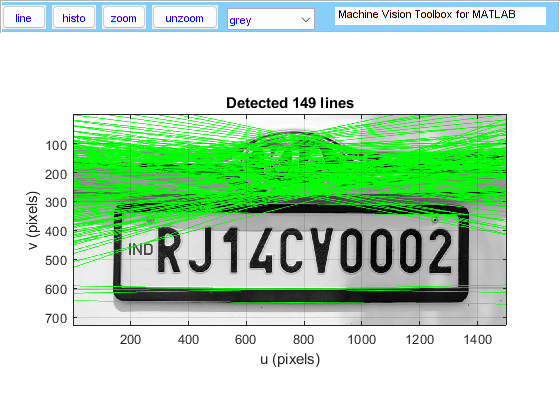

idisp(plate) , grid on, title(strcat("Detected ",string(numel(lines))," lines")) ;
h.plot('g')


% nonlocal maxima supression
h1 = Hough(edges, 'suppress', 4)

 
h1 = 
 
Hough: nd=401, ntheta=400, interp=3x3, distance=4
 


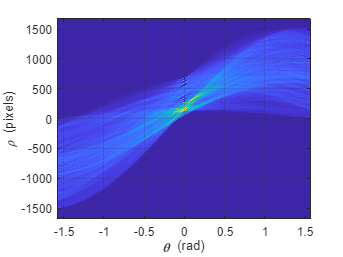

figure, h.show(), grid on ,

lines = h1.lines()

 
lines = 
 
theta=-0.00775619, rho=158.253, strength=1       
theta=-0.0409717, rho=115.019, strength=0.95457  
theta=0.0352154, rho=175.226, strength=0.895619  
theta=0.109419, rho=325.73, strength=0.884262    
theta=-0.00681461, rho=266.258, strength=0.802596
theta=-0.0150364, rho=591.829, strength=0.799892 
theta=-0.0942451, rho=116.985, strength=0.782044 
theta=0.068327, rho=290.66, strength=0.764197    
theta=0.142908, rho=369.206, strength=0.759329   
theta=-0.117106, rho=161.977, strength=0.732288  
theta=-0.00794563, rho=334.945, strength=0.676041
theta=0.184519, rho=383.741, strength=0.641428   
theta=-0.0510018, rho=174.529, strength=0.633856 
theta=0.223713, rho=408.997, strength=0.62358    
theta=0.0857447, rho=246.121, strength=0.616009  
theta=0.0162017, rho=220.682, strength=0.612764  
theta=-0.00753083, rho=643.463, strength=0.608978
theta=-0.17262, rho=-50.2165, strength=0.606274  
theta=-0.127656, rho=73.3098, strength=0.604651  
theta=0.0314159, rho=266.758, strengt

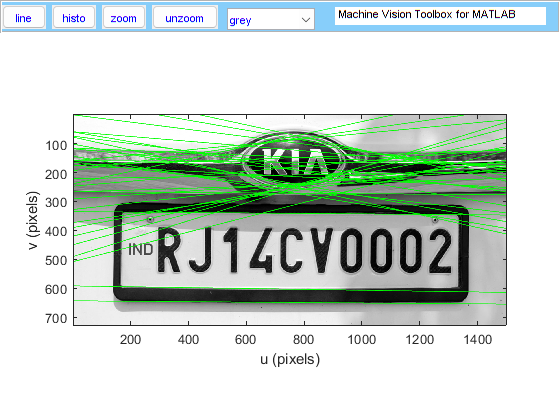

figure, idisp(plate);
h1.plot('g')


gradient=lines.rho.*tan(deg2rad(lines.theta));
low_slopes=find((-0.1<=gradient) & (gradient<=0.1));
rho_lines=zeros(numel(low_slopes),2);

for n=1:numel(low_slopes)
    rho_lines(n,1)=lines(low_slopes(n)).rho;
    rho_lines(n,2)=low_slopes(n);
end

figure, idisp(plate) ; grid on,

rho_lines=sortrows(rho_lines,1);

disp("Calculating differences")

Calculating differences


for n = 1:height(rho_lines)
    v_point1=rho_lines(n,1); 
    v_point2=rho_lines(n+1,1);
    difference(n)=v_point2-v_point1;
    disp(difference(n))
    if n==(height(rho_lines)-1)
        break
    end
end

   58.3341

   56.5950

   43.2334

   62.4295

   45.5755

   68.6870

  308.5186



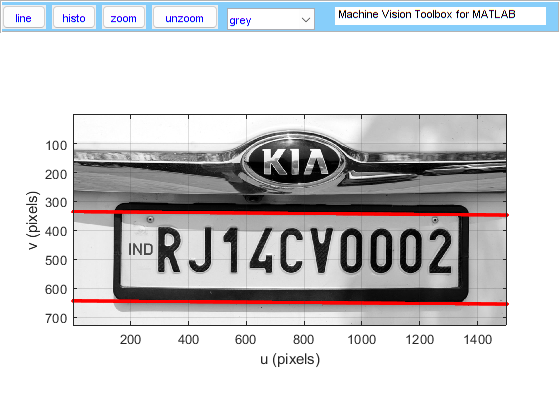


Nj=find(difference==max(difference));


lines(rho_lines(Nj,2)).plot('r.');
lines(rho_lines(Nj+1,2)).plot('r.');


horizontalpoint1=lines(rho_lines(Nj,2)).rho;
horizontalpoint2=lines(rho_lines(Nj+1,2)).rho;

%cropped_image=plate(lines(rho_lines(Nj,2)).rho:lines(rho_lines(Nj+1,2)).rho,:,:);
cropped_image=plate(horizontalpoint1:horizontalpoint2,:,:);

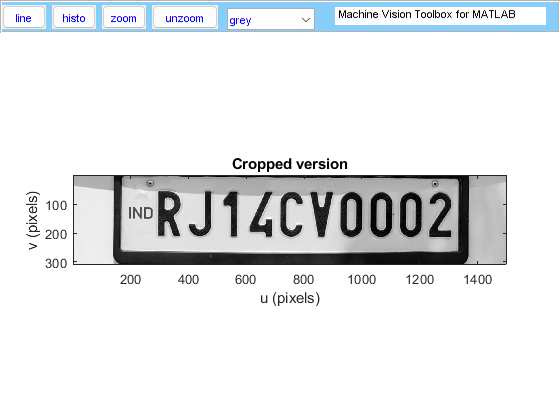

figure
idisp(cropped_image);
title("Cropped version");

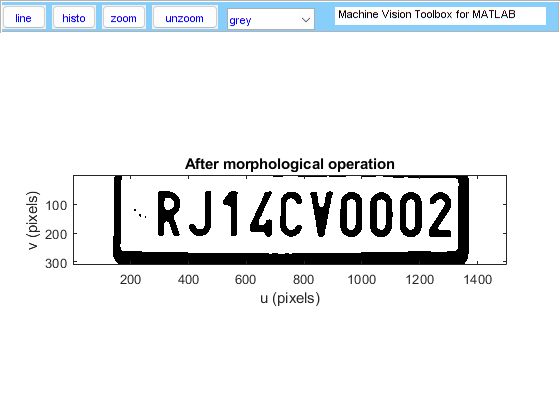


plate=morphology(cropped_image,round(lines(rho_lines(Nj+1,2)).rho-lines(rho_lines(Nj,2)).rho));

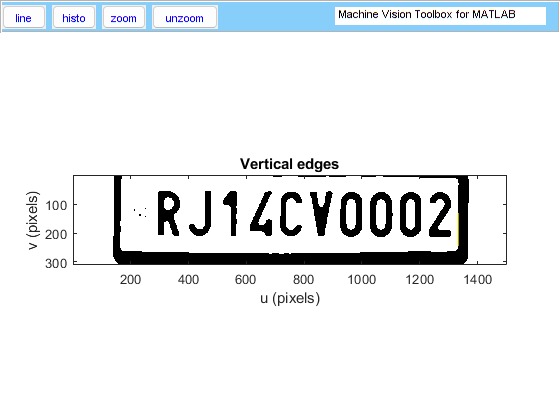

%plate=morphology(cropped_image,300);

plate=medfilt2(plate, [4 4]);

% figure
% idisp(plate);
% title("After median filtering");
% for n=1:Nj
%     lines(Nj).plot('r.');
% end

%% Vertical Hough edge transform

vertical_edges = edge(plate, 'Sobel', 'vertical');

% nonlocal maxima supression
[H,T,R]=hough(vertical_edges);
P  = houghpeaks(H,5,'threshold',ceil(0.6*max(H(:))));
lines = houghlines(vertical_edges,T,R,P,'FillGap',5);

for n=1:numel(lines)
    plate_vertical=insertShape(double(plate),'line',[lines(n).point1(1),lines(n).point1(2),lines(n).point2(1),lines(n).point2(2)],LineWidth=5);
end
figure
idisp(plate_vertical);
title("Vertical edges")

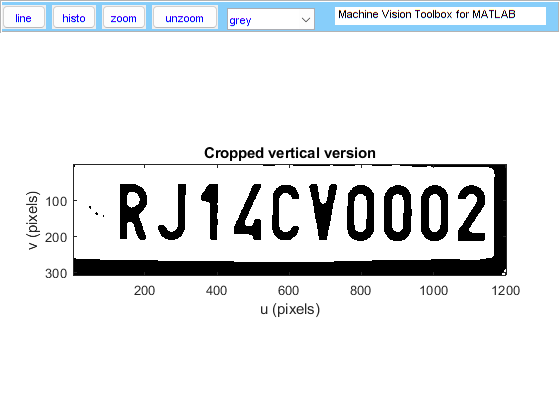


max_difference=0;
index=0;
for n=1:numel(lines)
    difference=abs(lines(1).point1(1)-lines(n).point1(1));
    if difference>max_difference
        max_difference=difference;
        index=n;
    end
end

verticalpoint1=lines(1).point1(1);
verticalpoint2=lines(index).point1(1);

plate=plate(:,min(verticalpoint1,verticalpoint2):max(verticalpoint1,verticalpoint2),:);
figure
idisp(plate);
title("Cropped vertical version");


%% Creating final image for blob analysis
plate=original_plate(horizontalpoint1:horizontalpoint2,min(verticalpoint1,verticalpoint2):max(verticalpoint1,verticalpoint2),:);

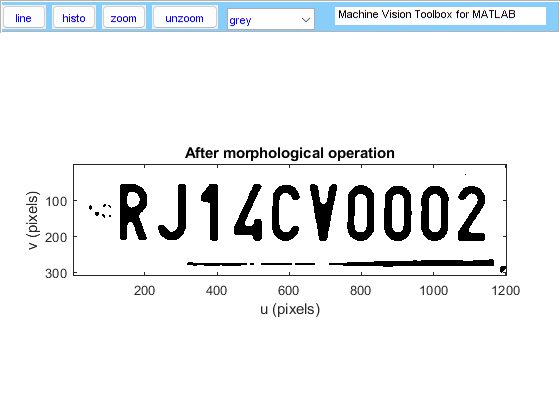

plate=morphology(plate,round(abs(horizontalpoint1-horizontalpoint2)));

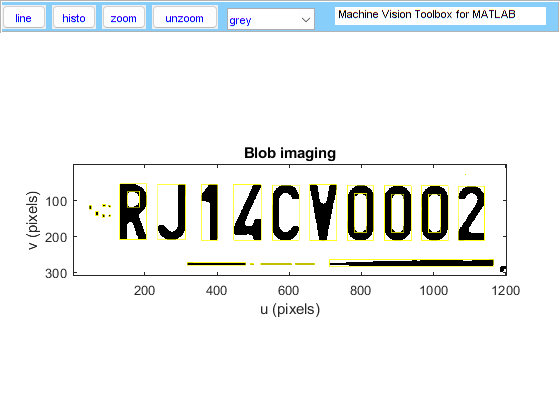

plate=medfilt2(plate, [4 4]);
figure
idisp(plate);
title("Final image before blob processing");


%% Finding blobs in image, identifying letters, reordering them, 
figure
idisp(plate)
title("Blob imaging")
letters=iblobs(plate);
for n=1:numel(letters)
    if letters(n).touch==0
        letters(n).plot_box('y')
        letter_heights(n)=(letters(n).vmax-letters(n).vmin);
    end
end



% Choose the number of clusters (K)
K = 4; % You need to decide the number of clusters

% Perform k-means clustering
[idx, centers] = kmeans(letter_heights, K);

% Initialize arrays to store cluster heights and cluster sizes
cluster_heights = zeros(1, K);
cluster_sizes = zeros(1, K);

max_cluster_size = 0; % Initialize maximum cluster size
max_cluster_height = 0; % Initialize maximum cluster height
max_valid_cluster_size = 12;


% Calculate the mean height for each cluster and count cluster sizes
for k = 1:K
    cluster_indices = (idx == k);
    cluster_heights(k) = mean(letter_heights(cluster_indices));
    cluster_sizes(k) = sum(cluster_indices);

    if cluster_sizes(k) < max_valid_cluster_size
        if cluster_sizes(k) > max_cluster_size
            max_cluster_size = cluster_sizes(k);
            max_cluster_height = cluster_heights(k);
        end
    end
end

% Display the estimated letter heights and cluster sizes
fprintf('Estimated Letter Heights and Cluster Sizes:\n');

Estimated Letter Heights and Cluster Sizes:


for k = 1:K
    fprintf('Cluster %d: Height=%.2f, Size=%d\n', k, cluster_heights(k), cluster_sizes(k));
end

Cluster 1: Height=5.00, Size=13
Cluster 2: Height=106.33, Size=3
Cluster 3: Height=30.50, Size=2
Cluster 4: Height=153.30, Size=10


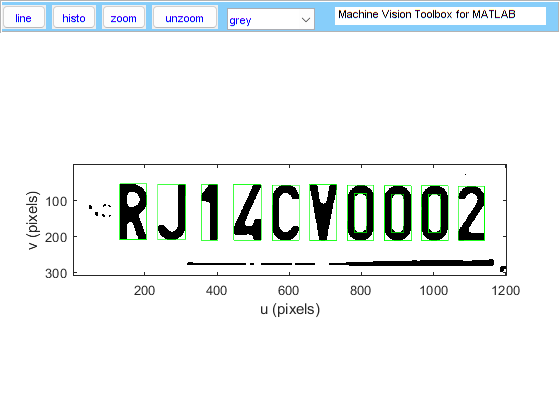


%letter_height=cluster_heights(find(cluster_heights==max(cluster_heights(find(cluster_sizes<9)))));
letter_height=max(cluster_heights(find(cluster_sizes<9)));
%letter_height=300;

figure
idisp(plate)

plate_letters=RegionFeature.empty(0);


position=1;
for n=1:numel(letter_heights)
    letter_centre=[letters(n).uc, letters(n).vc];
    if abs(((letter_heights(n)-letter_height)/letter_height)*100) <=50.0
        plate_letters(position)=letters(n);
        letters(n).plot_box('g');
        position=position+1;
    end
end


plate_letters = sortPlateLettersByValue(plate_letters);

for n=1:numel(plate_letters)
    possible_letter=plate_letters(n);
    if n==1
        plate_letters(n)=possible_letter;
    end
    if n~=1
        percentage_difference= abs((possible_letter.uc-plate_letters(n-1).uc)/plate_letters(numel(plate_letters)).uc)*100;
        if percentage_difference<=7
            disp("Same letter")
            if possible_letter.area > plate_letters(n-1).area
                plate_letters(n-1)=[];
            end
            if possible_letter.area < plate_letters(n-1).area
                plate_letters(n)=[];
            end
        end
    end
    if n >= numel(plate_letters)
        break
    end
end

Same letter
Same letter
Same letter


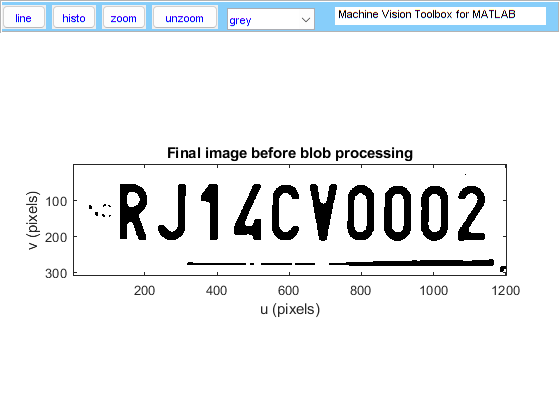

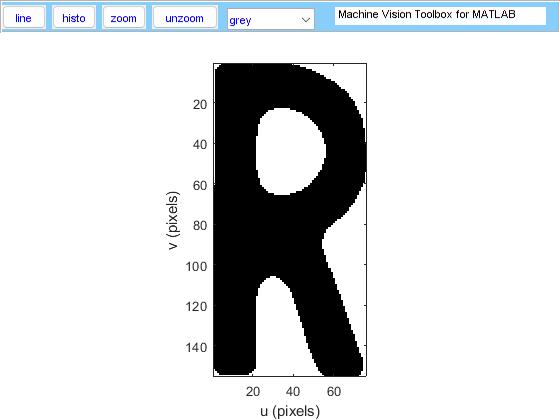

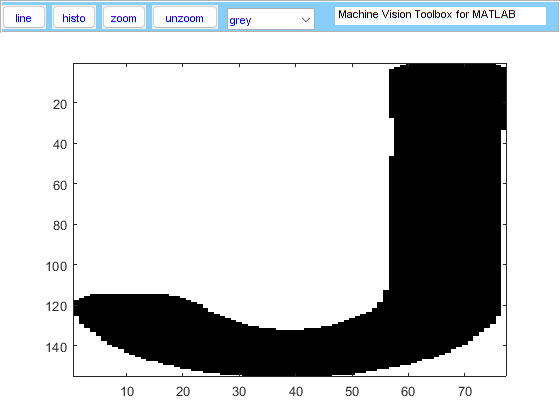

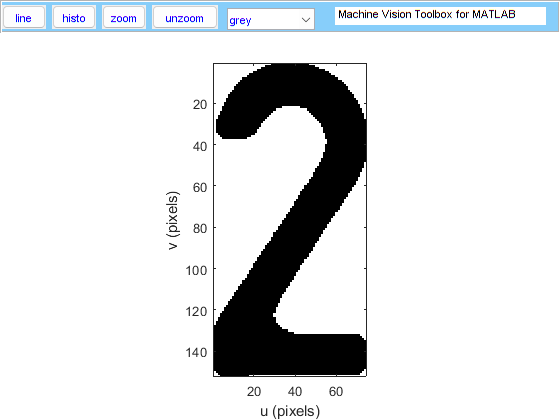


nonEmptyIndices = ~arrayfun(@isempty, plate_letters);

% Resize the array to remove empty elements
plate_letters = plate_letters(nonEmptyIndices);


plate_letter_collection=cell(length(plate_letters), 1);

figure
title("Letter")
for n=1:numel(plate_letters)
    plate_letter_collection{n}=plate(plate_letters(n).vmin:plate_letters(n).vmax,plate_letters(n).umin:plate_letters(n).umax,:);
    idisp(plate_letter_collection{n});
    pause(1);
end




%% Iterating over every letter in the blob image matrix to find template letter with highest match

matches=findBestMatches(plate_letter_collection, letter_templates);
text="";
for n=1:numel(matches)
    text=strcat(text,stringsplitter(matches{n}));
end

disp(text);

0000000000



%% Function Definitions


function [image]=blackandwhite(input)
plate=iread(input,'double');
gs = im2gray(plate);
gs = imadjust(gs);
H = fspecial("average",2);
gs = imfilter(gs,H,"replicate");
image=gs;
figure
idisp(plate);
title('before');
end

function [image]=morphology(input,height)
gs=input;
SEdisk = strel("rectangle",[height width(input)]);
%Ibg = imopen(gs,SEdisk);
Ibg = imclose(gs,SEdisk);
gsSub =  Ibg - gs;
gfilter=kgauss(2);
gsSub=iconv(gfilter,gsSub);
BW = ~imbinarize(gsSub);
BW=medfilt2(BW,[10,10]);
image=BW;
figure
idisp(image);
title('After morphological operation');
end

function [image]=blackandwhiteletter(input)
plate=iread(input,'double');
gs = im2gray(plate);
gs = imadjust(gs);
H = fspecial("average",2);
gs = imfilter(gs,H,"replicate");
gs=imbinarize(gs);
image=gs;
figure
idisp(plate);
title('before');
end

function [plate_letters] = sortPlateLettersByValue(plate_letters)
    % Extract the values from the objects into a numerical array
    letter_positions = [plate_letters.uc];

    % Sort the values in ascending order and obtain the sorted indices
    [sortedValues, sortedIndices] = sort(letter_positions);

    % Rearrange the objects based on the sorted indices
    plate_letters = plate_letters(sortedIndices);
end


function [your_matrix]=oddandeven(image)
[rows, cols] = size(image);
% Check if either dimension is even
if mod(rows, 2) == 0 || mod(cols, 2) == 0
    % If either dimension is even, make it odd
    if mod(rows, 2) == 0
        rows = rows + 1; % Increase the number of rows by 1
    end
    if mod(cols,2) == 0
        cols = cols + 1; % Increase the number of columns by 1
    end

    % Create a new matrix with the odd dimensions
    new_matrix = ones(rows, cols);

    % Copy the data from the old matrix to the new one
    new_matrix(1:size(image, 1), 1:size(image, 2)) = image;

    % Replace the old matrix in the workspace with the new one
    your_matrix = new_matrix;
else
    your_matrix=image;
end
end

function weightedAvg = weightedAverage(inputArray)
    % Initialize variables to store sum and count for each unique element
    uniqueElements = unique(inputArray);
    sumByElement = zeros(size(uniqueElements));
    countByElement = zeros(size(uniqueElements));
    
    % Calculate sum and count for each unique element
    for i = 1:length(uniqueElements)
        element = uniqueElements(i);
        elementIndices = (inputArray == element);
        sumByElement(i) = sum(elementIndices .* inputArray);
        countByElement(i) = sum(elementIndices);
    end
    
    % Calculate the weighted average
    weightedAvg = sum(sumByElement .* countByElement) / sum(countByElement);
end


function bestMatches = findBestMatches(blobImages, templateDatabase)
    % Initialize a cell array to store the best match file names
    bestMatches = cell(size(blobImages));
    
    % Iterate through each blob letter image
    for i = 1:length(blobImages)
        % Get the current blob letter image
        blobImage = double(blobImages{i});
        
        % Initialize variables to keep track of the best match
        bestMatchScore = inf; % Initialize with a high value
        bestMatchIndex = 0;   % Index of the best match template
        
        % Iterate through each template image in the database
        for j = 1:length(templateDatabase.Files)
            % Get the current template image
            templateImage = double(im2gray(imread(templateDatabase.Files{j})));
            
            % Resize the template image to match the size of the blob image
            templateImage = imresize(templateImage, size(blobImage));
            
            % Calculate a similarity score between the blob and template images
            % You can use a suitable similarity metric (e.g., mean squared error, correlation)
            similarityScore = calculateSimilarity(blobImage, templateImage);
            
            % Update the best match if the current score is better
            if similarityScore < bestMatchScore
                bestMatchScore = similarityScore;
                bestMatchIndex = j;
            end
        end
        
        % Store the file name of the best match in the result array
        bestMatches{i} = templateDatabase.Files{bestMatchIndex};
    end
end

function similarityScore = calculateSimilarity(image1, image2)
    % errorImage = image1 - image2;
    % squaredError = errorImage.^2;
    % meanSquaredError = mean(squaredError(:));
    % similarityScore = -meanSquaredError; % Negative for lower error values being better
    similarityScore=normxcorr2(image1,image2);
end


function letter=stringsplitter(address)
    % Define the input file path as a string
    parts = strsplit(address, '\');
    letter=strsplit(parts{numel(parts)},'.');
    letter=letter{1};
end
